# Pdf and Cdf of Poisson RV

Note: this script reproduces the figure of the Poisson RV in Section 2.1.5 of **Statistics for Chemical Engineers**: pdfs and cdfs for different rates, and realizations of P(1/2). Victor Z UW-Madison, 2020 pdf and cdf of a Poisson RV

clc; clear all; close all hidden;

## Different values of lambda

compare for different lambda

 lambda=[1/2 5 10];
color=["black","black","black"];
marker=["o-","x-","d-"];

x=0:1:20;

figure(1)

## Realizations

generate realizations

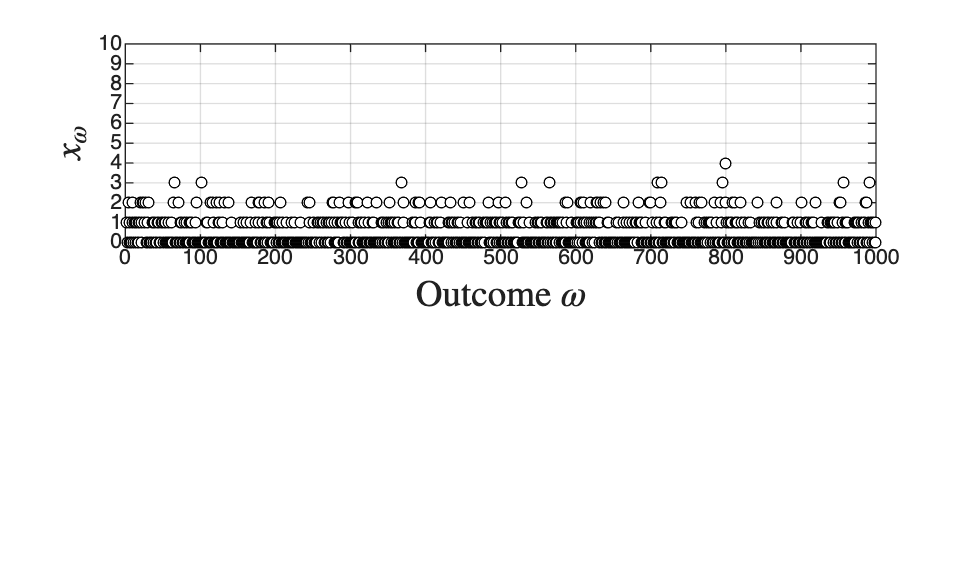

S=1000;
rng(0);
X = poissrnd(1/2,S,1);
figure(1)
subplot(2,2,[1 2])
plot(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on
yticks([0:1:15])
axis([0 S 0 10])

## Plots

visualize pdf

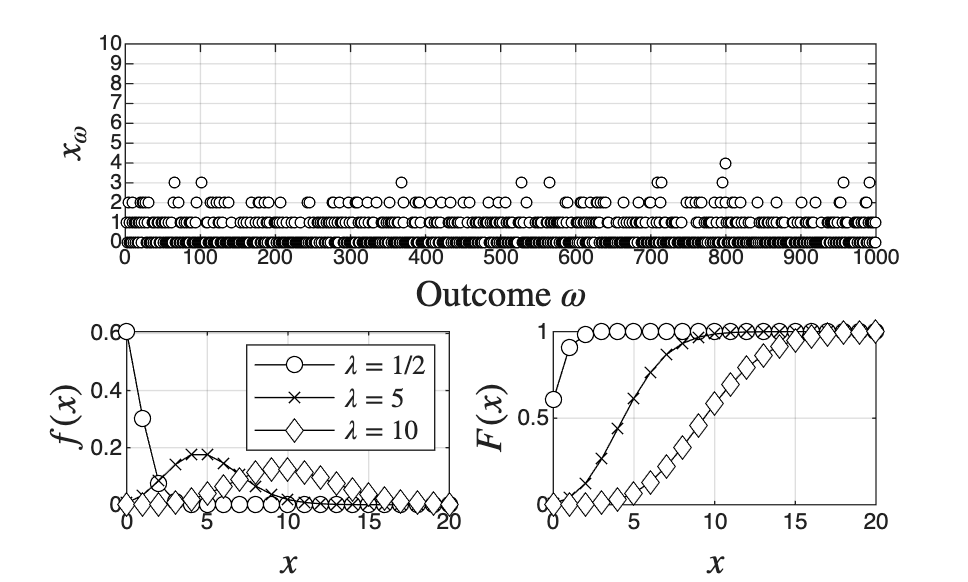

subplot(2,2,3)
for k=1:length(lambda)
plot(x,poisspdf(x,lambda(k)),marker(k),'MarkerFaceColor','w','MarkerEdgeColor',color(k),'Color',color(k))
hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
lgd=legend('$\lambda=1/2$','$\lambda=5$','$\lambda=10$','Interpreter','latex','location','northeast');
lgd.FontSize = 10;

% visualize cdf
subplot(2,2,4)
for k=1:length(lambda)
plot(x,poisscdf(x,lambda(k)),marker(k),'MarkerFaceColor','w','MarkerEdgeColor',color(k),'Color',color(k))
hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')

print -depsc ch2_pdfcdfpoisson.eps

## Note

The Poisson RV counts events in an interval; its pdf shifts to the right and spreads out as the rate lambda grows.